% param
flux_chaleur=-100;
Tini=25; % temperature initiale
Trad=100; % temperature resistance
h=1; % le pas


% matrice A
%A=diag(-4*ones(9,1))+diag(ones(8,1),-1)+diag(ones(8,1),1)+diag(ones(6,1),-3)+diag(ones(6,1),3)
A1=diag(-4*ones(3,1))+diag(ones(2,1),-1)+diag(ones(2,1),1)

A1 =     -4     1     0
     1    -4     1
     0     1    -4


A2=diag(ones(1,3))

A2 =      1     0     0
     0     1     0
     0     0     1


A3=zeros(3)

A3 =      0     0     0
     0     0     0
     0     0     0


A=[A1 A2 A3;
   A2 A1 A2;
   A3 A2 A1]

A =     -4     1     0     1     0     0     0     0     0
     1    -4     1     0     1     0     0     0     0
     0     1    -4     0     0     1     0     0     0
     1     0     0    -4     1     0     1     0     0
     0     1     0     1    -4     1     0     1     0
     0     0     1     0     1    -4     0     0     1
     0     0     0     1     0     0    -4     1     0
     0     0     0     0     1     0     1    -4     1
     0     0     0     0     0     1     0     1    -4


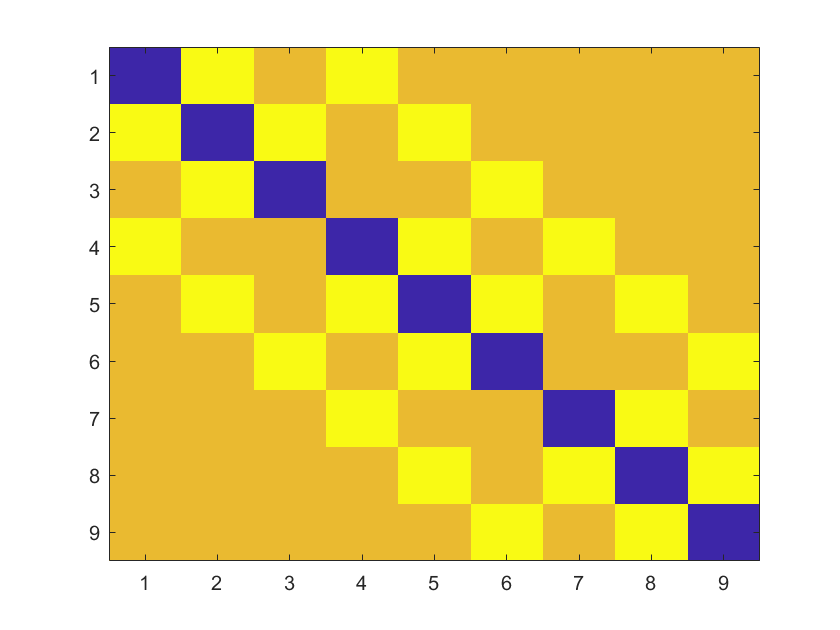


imagesc(A)



% matrice C
C=-2*Tini*ones(9,1);
C([4 6],1)=-Tini;
C([2 8],1)=flux_chaleur-Tini;
C(5,1)=flux_chaleur;
C

C =    -50
  -125
   -50
   -25
  -100
   -25
   -50
  -125
   -50


% vecteur Tvec
Tvec=A\C

Tvec =    43.7500
   75.0000
   43.7500
   50.0000
   87.5000
   50.0000
   43.7500
   75.0000
   43.7500


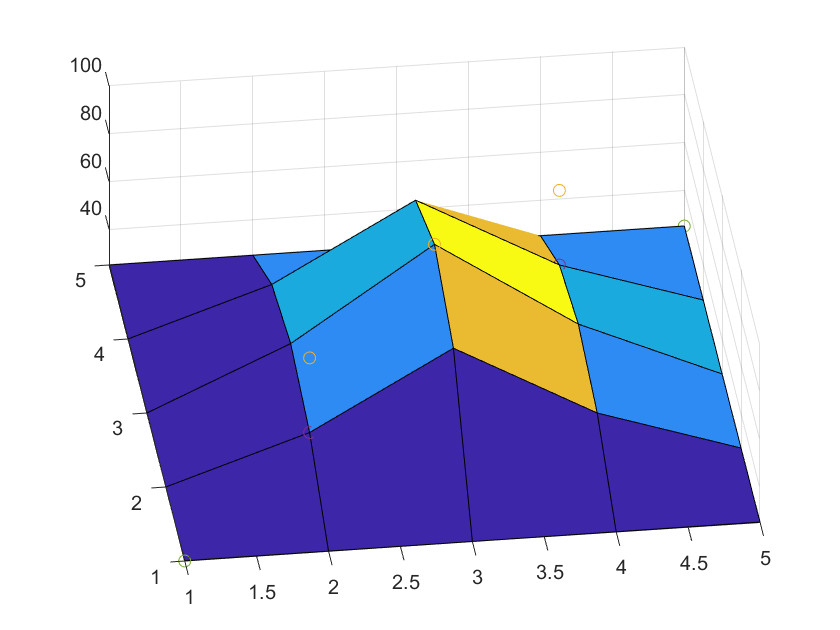





% matrice T finale
T=zeros(5);
T(5,:)=Tini;
T(:,1)=Tini;
T(:,5)=Tini;
T(1,:)=Tini;
T(2,2:4)=Tvec(1:3,1);
T(3,2:4)=Tvec(4:6,1);
T(4,2:4)=Tvec(7:9,1);
figure(1)
surf(T)
hold on 
plot3(1:5,1:5,T,'o')